# **M1 E3A**

# **TP1 (Image Processing)**

# **Mohammed Akib Iftakher (20215282)**

## **Image Loading**

### **Image 1**

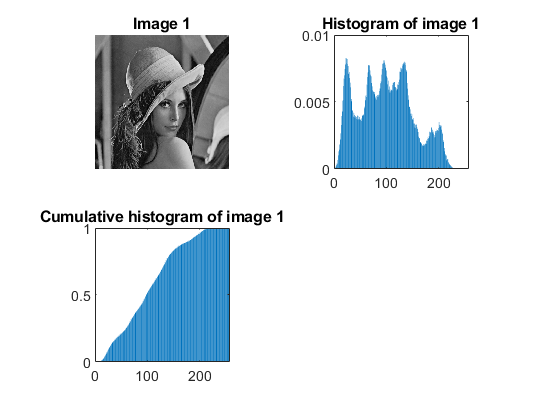

img1 = imread('lenna1.png');

imhisto = hist(img1(:),[0:255]);  
imhisto =imhisto/sum(imhisto);
imhistocum = cumsum(imhisto);

figure; subplot(2,2,1); imshow(img1,[]), title('Image 1');
subplot(2,2,2), bar(imhisto), axis square, title('Histogram of image 1'); 
subplot(2,2,3), bar(imhistocum), axis square, title('Cumulative histogram of image 1');

The histogram provides information about the image's exposure. The graph of image 1 begins to tilt to the left. The image is thought to be underexposed. This results in moderate shadows, which shifts the contrast to somewhat black.

### Image **2**

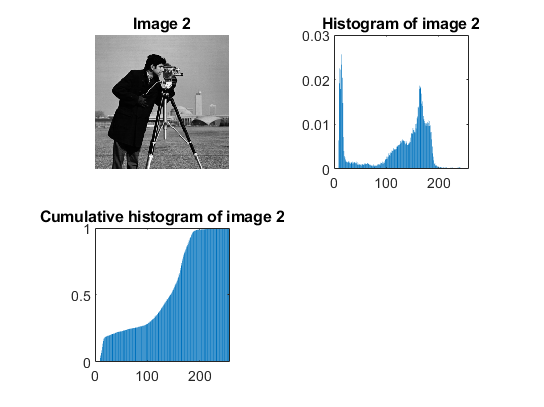

img2 = imread('cameraman.tif');

imhisto = hist(img2(:),[0:255]);  
imhisto =imhisto/sum(imhisto);
imhistocum = cumsum(imhisto);

figure; subplot(2,2,1); imshow(img2,[]), title('Image 2');
subplot(2,2,2), bar(imhisto), axis square, title('Histogram of image 2'); 
subplot(2,2,3), bar(imhistocum), axis square, title('Cumulative histogram of image 2');

The graph in Image 2 is better balanced since it is nearer to the center, also known as the midtones. This indicates that the image tones are more concentrated in the center. This also suggests that the image has a better brightness/darkness (luminosity) and contrast balance.

## Exercise 1 : Interpretation of frequency content 

### 1. The fft2 function allows you to calculate the Fourier transform of an image and the ifft2 function the inverse transform. The fftshift function allows you to center a Fourier transform on the fundamental (zero spatial frequency). Calculate the centered Fourier transform of an image of your choice in grayscale. Display the module or the real part of this transform either in an image or in a graphic (surf function, image, imagesc, imshow, etc.). We will use: log(1 + abs(fft2(I)).

#### **Fourier transform of Image 1**

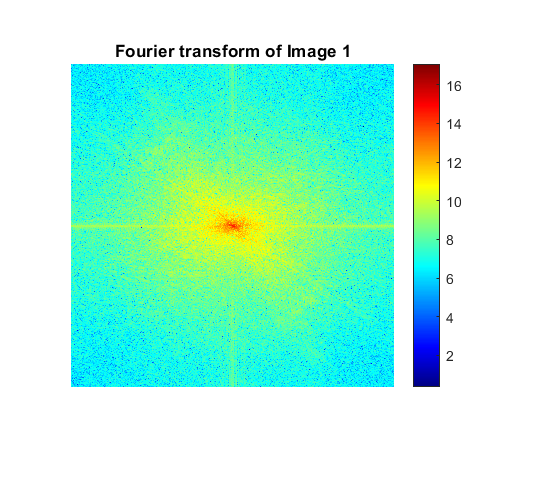

ft1 = fft2(double(img1)); %Calculate the DFT.

%To display zero-frequency coefficient in the center,
%you can use the function fftshift.
FS1 = fftshift(ft1);

%In Fourier transforms, high peaks are so high they
%hide details. Reduce contrast with the log function.

S1 = log(1+abs(FS1)); %%There are real and imaginary parts to img1. 
% So, abs needs to be used to get the magnitude. 

figure,imshow(S1,[]), title('Fourier transform of Image 1');colormap(jet); colorbar

#### **Inverse fourier transform of Image 1**

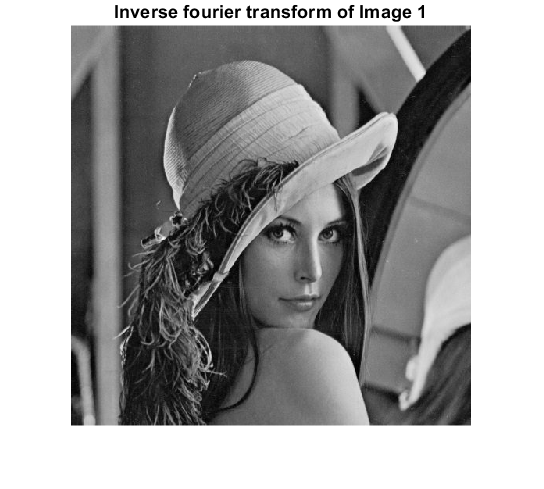

IFS1 = ifftshift(FS1);
ift1 = ifft2(IFS1);
figure,imshow(ift1,[]), title('Inverse fourier transform of Image 1');

After applying inverse fourier transform, it can be noted that the resulted image has the identical intensity of the main image. 

### **2. Where are the low frequencies, the high frequencies, the coefficients having the greatest amplitude? **

The image 1 shows that the low frequencies are in the center and the high frequencies are on the outside. The coefficients with the largest amplitude are located in the center. The majority of the information is at low frequencies (areas of low variation in intensity). The edges and fine detail are made up of high frequencies (areas of high variation in intensity). As a result, low frequencies are closer to the origin while high frequencies are further away from the origin. 

#### **Fourier transform of Image 2**

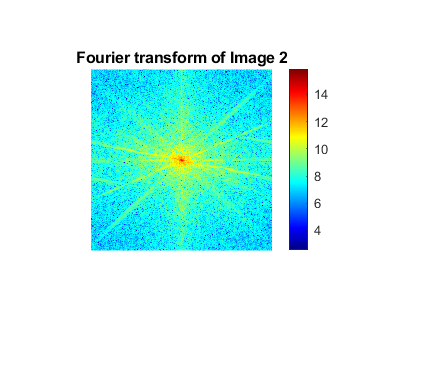

ft2 = fft2(double(img2));
FS2 = fftshift(ft2);

S2 = log(1+abs(FS2));

figure,imshow(S2,[]), title('Fourier transform of Image 2');colormap(jet); colorbar

#### **Inverse fourier transform**

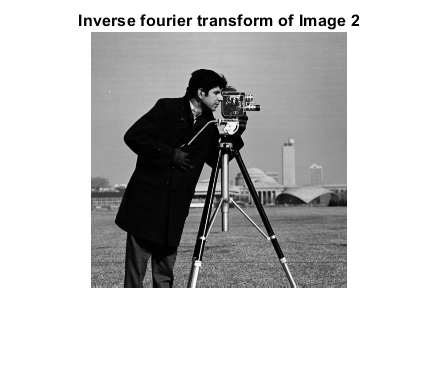

IFS2 = ifftshift(FS2);
ift2 = ifft2(IFS2);
figure,imshow(ift2,[]), title('Inverse fourier transform of Image 2');

The fourier transform of picture 2 shows that low frequencies dominate in the middle, while frequencies begin to increase as they approach the edges. Again, the frequencies correspond to coefficients with the greatest amplitudes in the center.

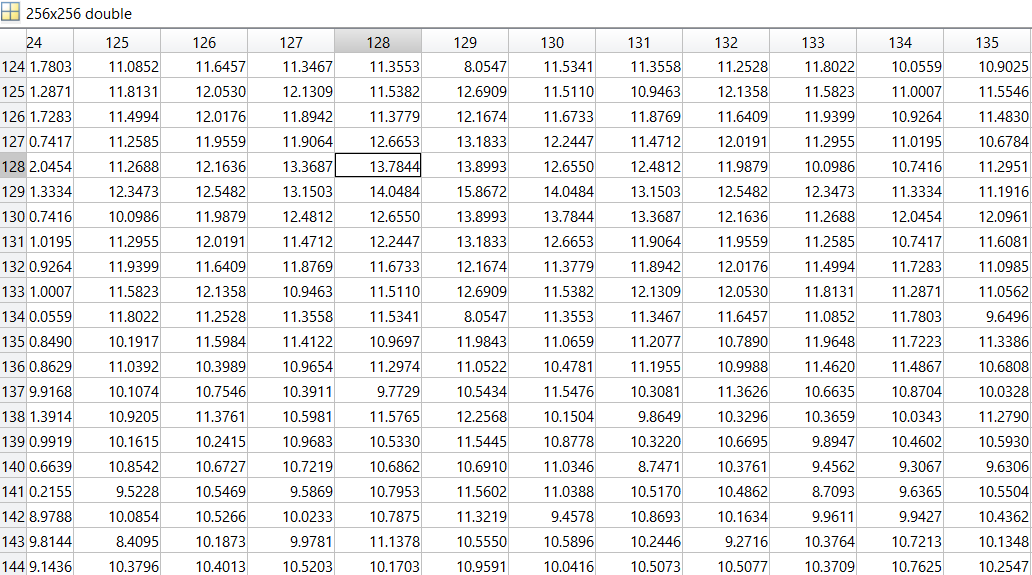

The snapshot of the intensity of the fourier transform shows that the intensity is highest near the middle.

### **3. Find the average of the gray levels of the image using the Fourier transform.**


[n,m]=size(img1);
x = sum(sum(img1))/(m*n) %summing over all the columns to create a row of sums and then summing across the row

x = 99.0612

y = ft1(1,1)/(m*n) %

y = 99.0612

It is clear from the above that the average of a greyscale image is equivalent to dividing the center point of the fourier transform by the total number of pixels. So, in summary, the center point of the fourier transform holds the same information as the average of the greyscale images.

#### **Image 2**

img2 = imread('cameraman.tif');

[N,M]=size(img2);
X = sum(sum(img2))/(M*N)

X = 118.7245


Y = ft2(1,1)/(M*N)

Y = 118.7245

From the image 2, it can seen again the relation between the average of the image and center point fo the fourier transform.

## **Exercise 2 : Properties of the Fourier transform **

### 1. **Linearity.** Warning: please handle typing correctly before each arithmetic operation. 

img3 = imread('image1.gif');
img4 = imread('image2.gif');

linear1 =fft2((img3))+fft2((img4));
total_image = double(img3)+double(img4);
linear2 =fft2(total_image);

diff = linear2-linear1;
figure;
%warning('off'); % removing the warning message.
imshow(diff); 

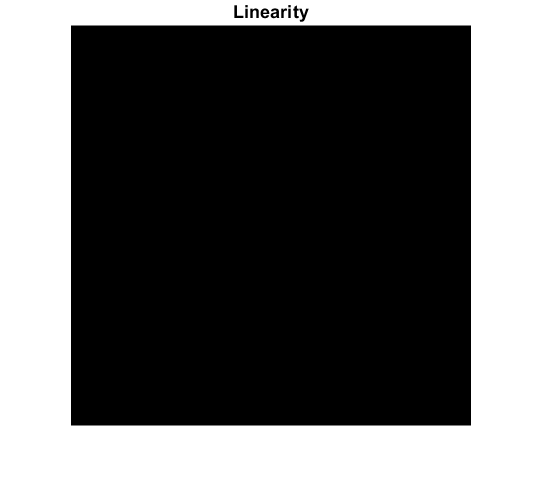

title("Linearity");

According to the Fourier transform's linearity feature, the Fourier transform of a weighted sum of two signals is identical to the weighted sum of their separate fourier transforms.

As a result, if the weighted total of two fourier transform signals is subtracted from the weighted sum of the separated fourier transforms, the result becomes nearly zero. A dark picture will appear in this situation.

### **2. Rotation. Hint: we can use imrotate. **

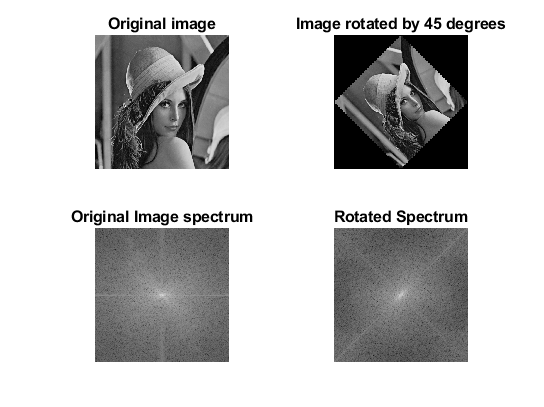

img1 = imread('lenna1.png');

ang = 45;
rotate=imrotate(img1,ang);
org_1=log(1+abs(fftshift(fft2(img1))));
rotate_1=log(1+abs(fftshift(fft2(rotate))));
figuimgb = imread('lenna1.png');

ang = 45;
rotate=imrotate(img1,ang);
org_1=log(1+abs(fftshift(fft2(img1))));
rotate_1=log(1+abs(fftshift(fft2(rotate))));

figure,
subplot(2,2,1);
imshow(img1);
title('Original image');

subplot(2,2,2);
imshow(rotate);
title('Image rotated by 45 degrees');

subplot(2,2,3);
imshow(mat2gray(org_1))
title('Original Image spectrum');

subplot(2,2,4);
imshow(mat2gray(rotate_1))
title('Rotated Spectrum');

The rotation property states that if an image in the spatial domain is rotated by a certain amount, the spectrum derived by DFT is likewise rotated by the same amount.

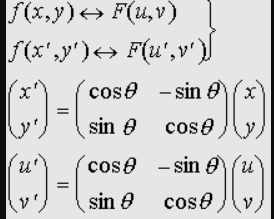

### 3. What is the result of the Fourier transform of I(x, y) × ${\left(-1\right)}^{x+y}$ ? What property of the Fourier transform is revealed? 

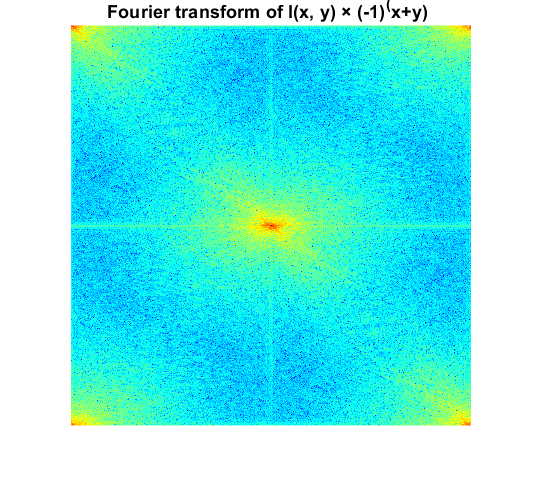

[n,m] = size(img1);
result = zeros(n,m);
for c = 1:n
    for r = 1:m
        result(r,c) =img1(r,c) *((-1).^(r+c));
    end
end

% figure;
% imshow(fft2((result)));
figure;
ft1 = fft2((result));
FS1 = fftshift(ft1);
S2 = log(1+abs(FS1));
figure;
imshow(S2, []);colormap(jet);
title('Fourier transform of I(x, y) × (-1)^(x+y) ');

Its showing the property of translation.

## Exercise 3 : Fourier transform of basic images 

### **1. A sinusoid function : sin( **$x\times y$** ) then sin(x) and sin(y). Note: A sinusoidal image in grayscale is obtained by: I(x, y) = **$255\times \frac{\sin \left(2\pi \left(\textrm{Ax}+\textrm{By}\right)+1\right)}{2}$

### **A and B are the frequencies (inverse of the period) for the vertical and horizontal displacement of the sine respectively. Test for several values of A and B (0, 1, 128/256, 64/256, 32/256, 16/256, etc.).**

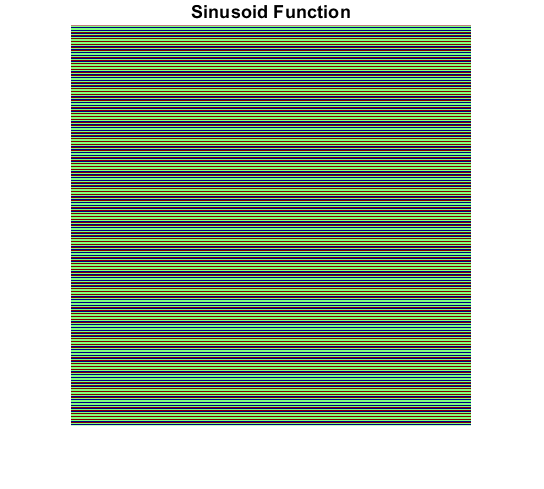

A=0.25; 
B= 0;
M=512; 
N=512;
f = zeros(M, N);
for c = 1:N
for r = 1:M
f(r, c) = 255*(sin(2*pi*(A*r + B*c))+1)/2;
end
end

figure, imshow(f, []);
title('Sinusoid Function'), colormap("jet");

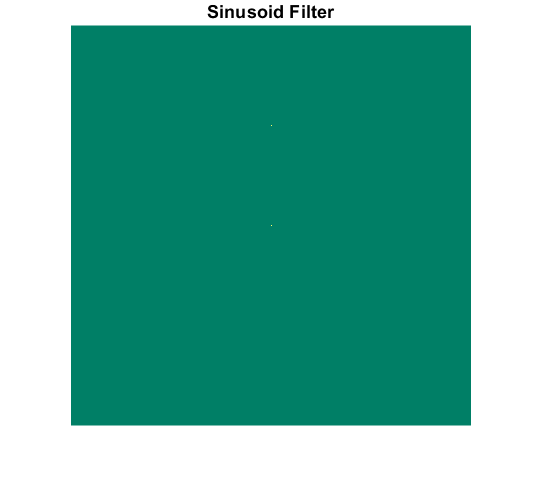



ft_I = fft2(double(I));
FS_I = fftshift(ft_I);

sin_f = log(1+abs(FS_I));
figure;
imshow(sin_f, []);
title('Sinusoid Filter'), colormap("summer")

This displays images with their Fourier Transforms just beneath them. The picture shows a 170 cycle pure vertical sine wave. The FT for each only has a single component, which is represented by three bright spots symmetrically positioned around the center of the FT picture. The frequency coordinate system's origin is located in the image's center. The horizontal component of frequency is represented by the u-axis, which runs from left to right through the center. The vertical component of frequency is represented by the v-axis, which goes from bottom to top through the middle. In these circumstances, a dot in the middle symbolizes the image's (0,0) frequency term or average value. Images usually have a large average value (like 128) and lots of low frequency information so FT images usually have a bright blob of components near the center. Notice that high frequencies in the vertical direction will cause bright dots away from the center in the vertical direction.Images often have a high average value (such as 128 or 255) and a lot of low frequency information, resulting in a bright blob of components at the center of the image. High frequencies in the vertical direction cause bright spots to appear further from the center in the vertical direction.

### **2. A gate function (image of a rectangle).**

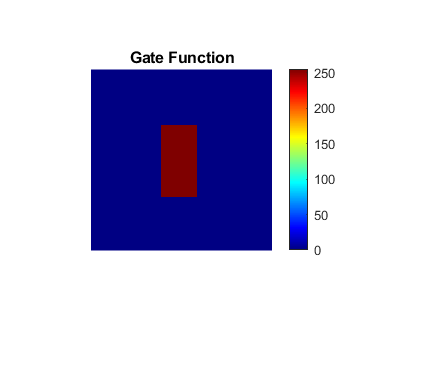

gate = zeros(256,256);
gate(80:180,100:150) = 255;
figure, imshow(gate, []);colormap(jet); colorbar
title('Gate Function')

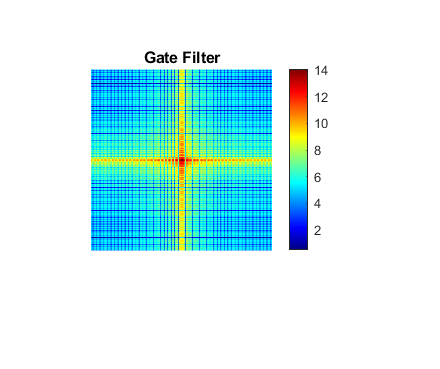


ft_gate = fft2(double(gate));
FS_gate = fftshift(ft_gate);
gate_f = log(1+abs(FS_gate));
figure;
imshow(gate_f, []);colormap(jet); colorbar;
title('Gate Filter')

The Fourier transform represents an image as a sum of complex exponentials with different magnitudes, frequencies, and phases. If f(m,n) is a function of two discrete spatial variables m and n, then the relationship defines the two-dimensional Fourier transform of f(m,n).

Variables ω1 and ω2 are frequency variables with units of radians per sample. F(ω1,ω2) is frequently referred to as the frequency-domain representation of f(m,n).

### **3. A Gaussian (use fspecial).**

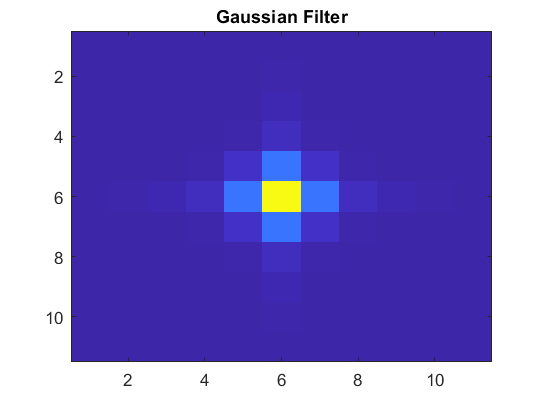

gauss = fspecial('gaussian',[11 11],4); %gaussian low-pass filter
FS_gauss = fftshift(fft2(double(gauss)));
abs_FS_gauss = abs(FS_gauss); 
gauss_f = log(1+abs_FS_gauss);
figure;
imagesc(gauss_f)
title('Gaussian Filter')

% plot(h(128, :))

This function produces a circular Gaussian lowpass filter with standard deviation SIGMA of size HSIZE. It is possible to smooth an image with a Gaussian spatial filter. The Gaussian smoothing operator is a two dimensional convolution operator used to 'blur' pictures by removing detail and noise. It is comparable to the average filter in this regard, but it employs an unique kernel that depicts the form of a Gaussian ('bell-shaped') hump.

### Application

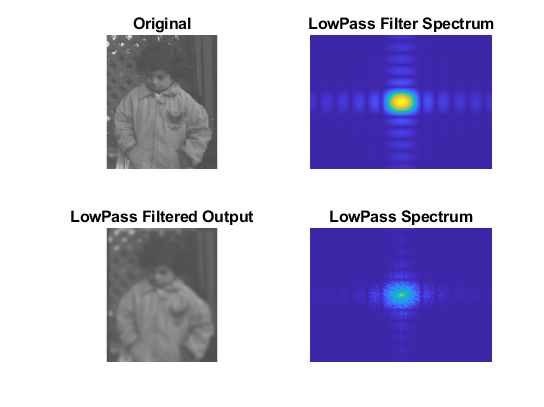

I=imread('pout.tif');
I=im2double(I);
FI=fft2(I); % Obtain the Fourier transform
LP=fspecial('gaussian',[11 11],4); % Generate a Low-Pass filter
FLP=fft2(LP,size(I,1),size(I,2)); % Filter padding
LP_OUT=FLP.*FI; % Multiply the transform by the filter
I_OUT_LP=ifft2(LP_OUT); % inverse DFT
I_OUT_LP=real(I_OUT_LP); % Obtain the real part(Output)

%%%%spectrum%%%%
FLP_S=abs(fftshift(FLP));%Filter spectrum
LP_OUT_S=abs(fftshift(LP_OUT));%output spectrum
subplot(221),imshow(I),title('Original'),
subplot(222),imagesc(log(1+FLP_S)),title('LowPass Filter Spectrum'),axis off
subplot(223),imshow(I_OUT_LP),title('LowPass Filtered Output')

subplot(224),imagesc(log(1+LP_OUT_S)),title('LowPass Spectrum'),axis off

### **4. A Uniform average filter (use fspecial). Compare with Gaussian in terms of frequency content.**

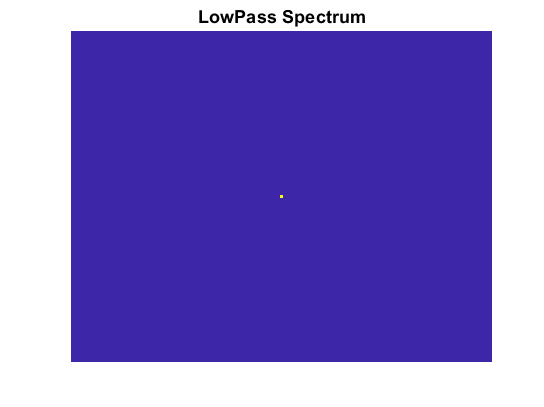

avg = fspecial('average', 121);

FS_avg = fftshift(fft2(double(avg)));
abs_FS_avg = abs(FS_avg); 
avg_f = log(1+abs_FS_avg);
figure;
imagesc(avg_f),title('LowPass Spectrum'),axis off

The average filter is used to smooth out images. It also lowers the intensity fluctuation. As a result, it may be argued that it is utilized to reduce noise. The average filter is used to simplify greyscale photographs.

### Application

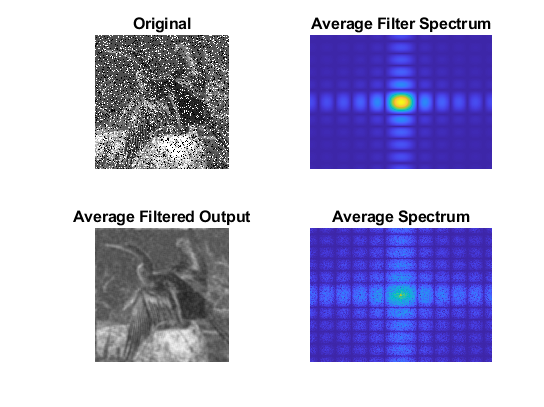

I1=imread('image3.gif');
I2=im2double(I1);
B = imnoise(I2, 'salt & pepper', 0.2);
FI=fft2(B); % Obtain the Fourier transform
Avf=fspecial('average', [11 11]); % Generate average filter
FAvf=fft2(Avf,size(B,1),size(B,2)); % Filter padding
Avf_OUT=FAvf.*FI; % Multiply the transform by the filter
I_OUT_Avf=ifft2(Avf_OUT); % inverse DFT
I_OUT_Avf=real(I_OUT_Avf); % Obtain the real part(Output)

%%%%spectrum%%%%
FAvf_S=abs(fftshift(FAvf));%Filter spectrum
Avf_OUT_S=abs(fftshift(Avf_OUT));%output spectrum
subplot(221),imshow(B),title('Original'),
subplot(222),imagesc(log(1+FAvf_S)),title('Average Filter Spectrum'),axis off
subplot(223),imshow(I_OUT_Avf),title('Average Filtered Output')

subplot(224),imagesc(log(1+Avf_OUT_S)),title('Average Spectrum'),axis off

### **5. A Laplacian filter (use fspecial). For each case, comment the obtained results. Make a link with the theoretical results seen in class. Do not hesitate to vary the parameters and to refer to the figure of the appendix to implement the padding for the generated filters of reduced size.**

 alpha controls the shape of the Laplacian

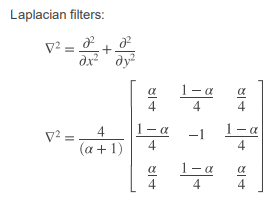

**Here the alpha has been changed twice to see the difference between the two different filter.**

**alpha = 0.2 & 0.6**

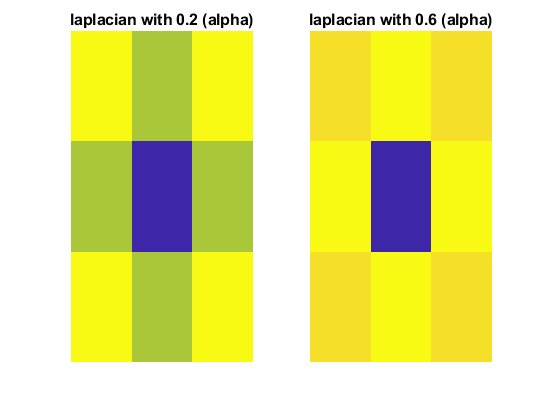

lap = fspecial('laplacian',0);
FS_lap = fftshift(fft2(lap));
abs_FS_lap = abs(FS_lap); 
lap_f = log(1+abs_FS_lap);


lap_06 = fspecial('laplacian',0.6);
FS_lap_06 = fftshift(fft2(lap_06));
abs_FS_lap_06 = abs(FS_lap_06); 
lap_f_06 = log(1+abs_FS_lap_06);

figure;
subplot(121),imagesc(lap_f),title('laplacian with 0.2 (alpha)'),axis off;
subplot(122),imagesc(lap_f_06),title('laplacian with 0.6 (alpha)'),axis off;

This is referred to as a discrete Laplacian. The laplacian has an advantage over first derivative approaches in that it is an isotropic filter, which implies that it is rotationally invariant. That is, if the laplacian is imposed to an image and afterwards rotated, the outcome will be the equivalent as if the image is rotated first and then the laplacian is applied. As a result, this class of filters appears to be suitable for edge detection. However, a significant issue with all second derivative filters is that they are extremely susceptible to noise.

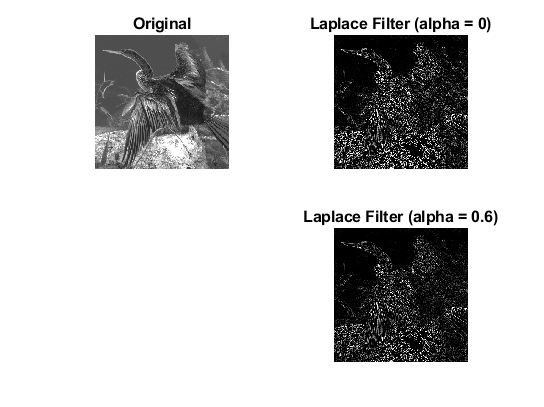

I2=im2double(I1);
FI=fft2(B); % Obtain the Fourier transform
cf = filter2(lap,I1);
cf_06 = filter2(lap_06,I1);

% figure, imshow(cf/100);
figure,
subplot(221),imshow(I1),title('Original'),
subplot(222),imshow(cf/100),title('Laplace Filter (alpha = 0)')
subplot(224),imshow(cf_06/100),title('Laplace Filter (alpha = 0.6)')

With the increase of the alpha, the edges starts to reduce. Because the kernels are attempting to approximate a second derivative measurement on the image, they are extremely susceptible to noise.  

## **Exercise 4 : Fourier transform and convolution**

### **Show that a convolution in the spatial domain is equivalent to a multiplication in the frequency domain. Demonstrate this property with a Laplacian (as it was generated in the previous exercise). Comment on the obtained result.**

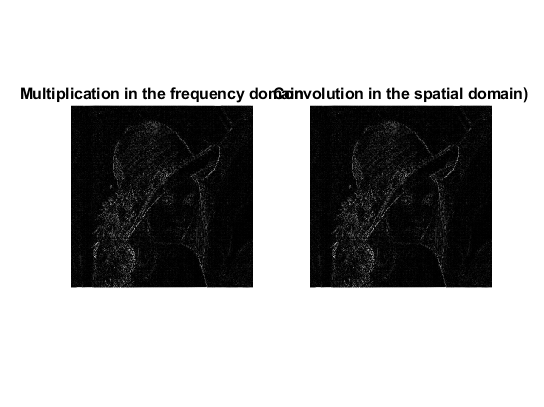

f = imread('lenna1.png');
h = fspecial('laplacian');
PQ = paddedsize(size(f)); %determines the proper padding amount 
% in order to minimize wraparound artifacts

% Creating the Frequency Filtered Image
F = fft2(double(f), PQ(1), PQ(2));
H = fft2(double(h), PQ(1), PQ(2));
F_fH = H.*F;
ffi = ifft2(F_fH);
ffi = ffi(2:size(f,1)+1, 2:size(f,2)+1);

% Creating the Spacial Filtered Image

img8 =conv2(double(f),h,'same');
figure
subplot(121),imshow(abs(ffi),[]),title('Multiplication in the frequency domain')
subplot(122),imshow(abs(img8), []),title('Convolution in the spatial domain)')

By observing the results, it can be mentioned that both of the image has similar edges. 

The following is the relationship between the spatial domain and the frequency domain:

or 

This implies that the convolution of the corresponding functions in the spatial domain corresponds to the multiplication of two Fourier transformations. This means that linear spatial filters may be performed as a simple component-wise multiply in the frequency domain.

## **Exercise 5 : Sampling **

### **1. Calculate the Fourier transform of a pulse train of the period of your choice. To generate an image 256 **$\times$** 256 with a pulse train of period 4 pixels: A = zeros (4,4); A (1.1) = 1; B = repmat (A, 256/4,256/4);**

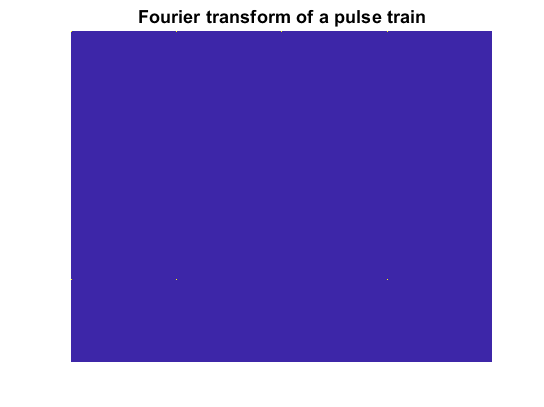

A = zeros (4,4);
A (1,1) = 1;
B = repmat (A, 512/4,512/4); % Repeat copies of array
fft_pulse = fftshift(fft2(B));
abs_pulse = abs(fft_pulse); 
log_pulse = log(1+abs_pulse);
figure;
imagesc(log_pulse),colormap('default'), axis off, title('Fourier transform of a pulse train')

### 2. Sample the image of your choice then the UCSB image using the generated pulse train. Note: multiply the image with the pulse train.

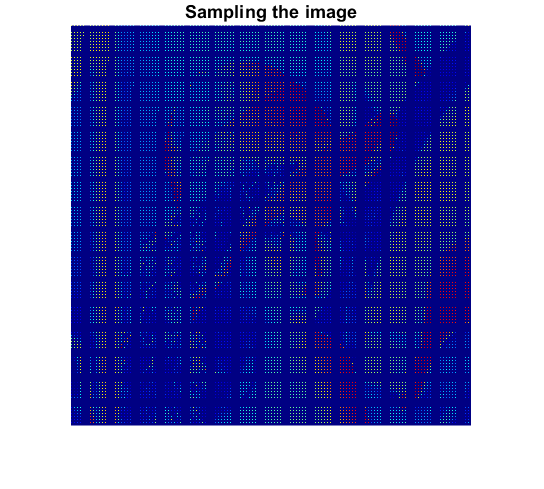

img6 = B.*double(img1);
figure, imshow(img6, []), title('Sampling the image'), colormap('jet')

### 3. Calculate the 2D DFT of the sampled image. Make the link with the theoretical results seen in class.

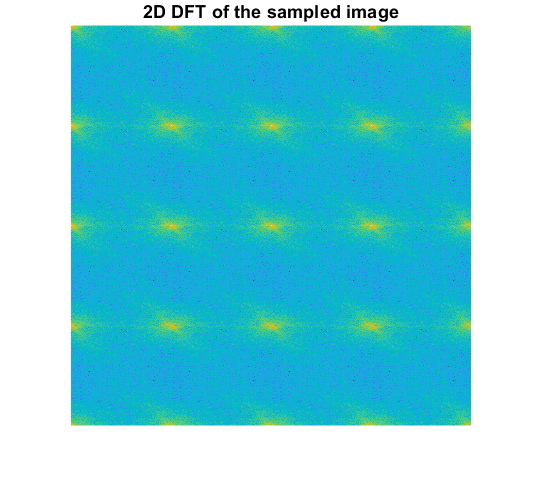

x = fftshift(fft2(img6));
y1 = abs(x); 
im2 = log(1+y1);
figure, imshow(im2, []), title('2D DFT of the sampled image'), colormap('default')

Here, the sampled function is 

Where, f(t) = main image and $\amalg_{\bigtriangleup T}$ = pulse train. 

The fourier transform of the above equation is

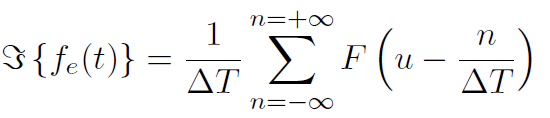

If we look close to the final result, it can be seen that the fourier transform has been shifted in sequential manner which signifies the numerator relation of $\Delta T$. 

## **Exercise 6 : Filtering in the frequency domain **

**1. Implement a low-pass filtering then a high-pass filtering on the image of your choice. What do these two operations achieve? We will compare ideal filters with Butterworth filters, taking care to vary the cutoff frequencies (0:25, 0:5, etc.). Reminder: H(u, v) = **$\frac{1}{1+{\left(\frac{D\left(u,v\right)}{D_0 }\right)}^{2n} }$** where n is the order of the filter, **$D_0$** the frequency cutoff and**$D\left(u,v\right)=\sqrt{u^2 +v^2 }$

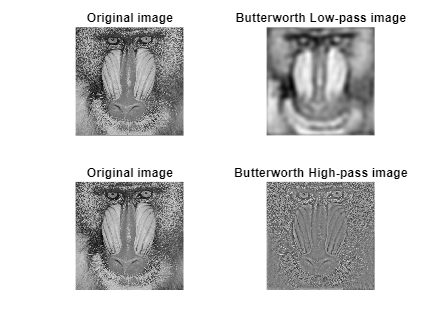

	
% Loading the image
ip_img = imread('image2.gif');

% Initializing the size of the input_image in pixels-
[M, N] = size(ip_img);

% Fourier Transform of the ip_img (2D fast fourier transform)
FT_img = fft2(double(ip_img));

% the order value of the filter
n = 10;

% the Cut-off Frequency
D0 = 15;

% The filter design filter
u = 0:(M-1);
v = 0:(N-1);
idx = find(u > M/2);
u(idx) = u(idx) - M;
idy = find(v > N/2);
v(idy) = v(idy) - N;


% 2D grid which contains the coordinates of vectors v and u.
[V, U] = meshgrid(v, u);

% Calculating Euclidean Distance
D = sqrt(U.^2 + V.^2);

% determining the filtering mask
H_low = 1./(1 + (D./D0).^(2*n)); % Low-pass filter

H_high = 1./(1 + (D0./D).^(2*n)); % High-pass filter

% Convolution between the Fourier Transformed image and filter
G_low = H_low.*FT_img;
G_high = H_high.*FT_img;

% the final image by Inverse Fourier Transform
op_image_low = real(ifft2(double(G_low)));
op_image_high = real(ifft2(double(G_high)));

figure,	
% Displaying Input Image and Output Image
subplot(2, 2, 1), imshow(ip_img), title('Original image')
subplot(2, 2, 2), imshow(op_image_low, [ ]), title('Butterworth Low-pass image')
subplot(2, 2, 3), imshow(ip_img), title('Original image'), title('Original image')
subplot(2, 2, 4), imshow(op_image_high, [ ]),  title('Butterworth High-pass image')

The Butterworth Lowpass Filter (BLPF) is a frequency domain image smoothing filter applied in image processing. It eliminates high-frequency distortion from a digital picture while preserving low-frequency components. On the otherhand, the Butterworth highpass filter operates in the opposite manner of the Butterworth lowpass filter. The Butterworth Highpass Filter (BHPF) is a frequency domain image sharpening filter. Image sharpening is a technique for enhancing small details and emphasizing edges in digital images. It subtracts low-frequency components from a picture while retaining high-frequency components.